# Exercise 4.4 - Bitcoin price history

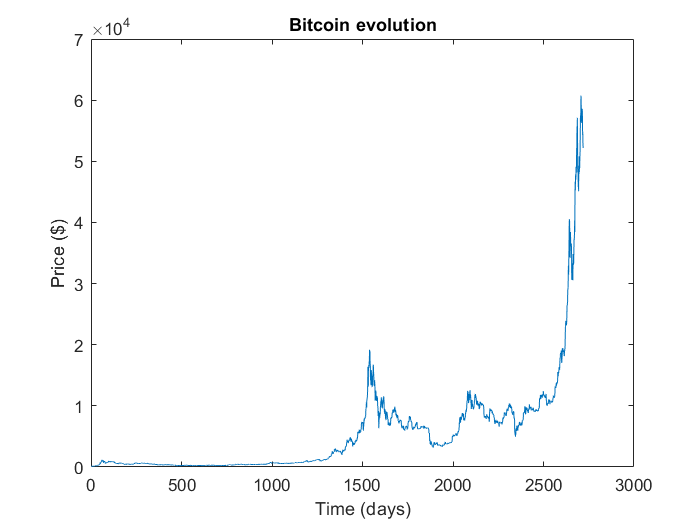

% Load price values into an array.
coin = csvread('data\coindeskall.csv', 1, 2);
bitcoin = coin(:, 1); % Select column.

% Plot bitcoin price history (since 2013).
plot(bitcoin)
title("Bitcoin evolution")
xlabel('Time (days)'), ylabel('Price ($)')

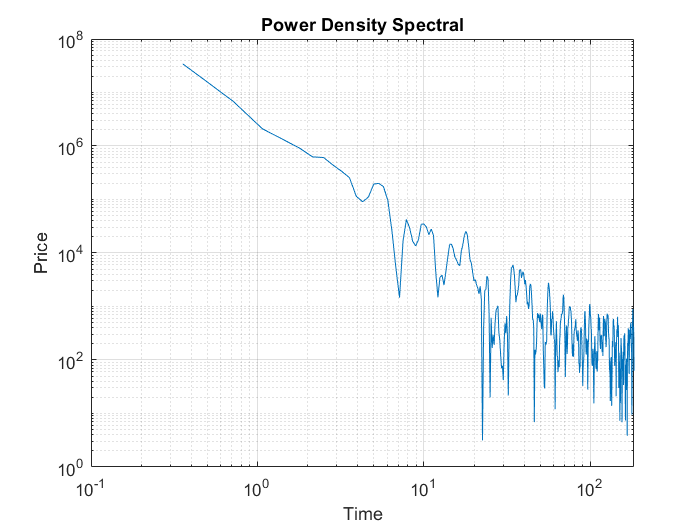


% Plot DSP, to see the distribution of power as a function of frequency. 
% We shall use logarithmic scale.
[Pxx, f] = pwelch(bitcoin, 1000, 0, [], 365);
figure, loglog(f, Pxx), grid
title("Power Density Spectral")
xlabel("Time"), ylabel("Price")